# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.2  最优化

#### 3.2.1 梯度下降法实现曲线拟合

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

clear; clc;
t = [ 0.1350, 0.2600, 0.3800, 0.5050, 0.6450, 0.8100, 1.0000, 1.2150, 1.4600, 1.7400, 2.0550, 2.4150, ...
       2.8150, 3.2650, 3.7650, 4.3200, 4.9350, 5.6100, 6.3450, 7.1500, 8.0200, 8.9650, 9.9800, 11.0650, ...
       12.2200, 13.4500, 14.7500, 16.1150, 17.5450, 19.0400, 20.5950, 22.1950, 23.8450, 25.5350, ...
       27.2600, 29.2650, 32.2700, 36.2800, 41.4850, 47.8900, 55.8950, 65.5000, 77.5050, 92.3100, ...
      108.7150, 128.3250, 151.9300, 179.9350, 212.9400, 252.9450]';
M = length(t);
% 构造模型
A =1800;
B = 15;
qMrl = 5;
AA = 50;
C = 10;
rng('default');
ratio = 0;
noise = ratio * randn(M, 1);
Et = A * exp(-t / B - 0.5 * qMrl * t.^2) + AA * exp(-t / B) + C + noise;
% 梯度下降法学习
% 初始参数
alpha = 1;   % 学习率大收敛快，可能有震荡
iteMax = 1000000;
iniA = 1;
iniB = rand;
iniQMrl = rand;
iniAA = rand;
iniC = rand;
initW = [iniA; iniB; iniQMrl; iniAA; iniC];
err = 1e-6;
J = zeros(iteMax, 1);
G = zeros(size(initW));
e = 0.1;
convIter = 0;
for i = 1 : iteMax
    gradA = 2 * iniA * exp(- 0.5 * iniQMrl^2 * t.^2 - t / iniB^2);
    gradB = (2 * iniA^2 * t .* exp(-0.5 * iniQMrl^2 * t.^2 - t / iniB^2)) / iniB^3 + (2 * iniAA^2 * t .* exp(-t /iniB^2)) / iniB^3;
    gradQMrl = - iniA^2 * iniQMrl * t.^2 .* exp(-0.5 * iniQMrl^2 * t.^2 - t / iniB^2);
    gradAA = 2 * iniAA * exp(-t / iniB^2);
    gradC = 2 * iniC * ones(M, 1);
    grad = 1 / M * [gradA, gradB, gradQMrl, gradAA, gradC]' * (iniA^2 * exp(-t / iniB^2 - 0.5 * iniQMrl^2 * t.^2) + iniAA^2 * exp(-t / iniB^2) + iniC^2 - Et);
    % Adagrad 法    x = x + yita * inv(G) * grad;
    G = G + grad.^2;
    newW = initW - alpha * diag(1 ./ sqrt(G + e)) * grad;
%     newW = initW - alpha * grad;
    if max(abs((newW - initW))) < err
        convIter = convIter + 1;
        if convIter == 10
            J(i + 1 : end) = [];
            disp(['梯度下降法迭代次数：', num2str(i)]);
            result = newW';
            result(1) = newW(1)^2;
            result(2) = newW(2)^2;
            result(3) = newW(3)^2;
            result(4) = newW(4)^2;
            result(5) = newW(5)^2;
            disp(['梯度下降法迭代结果：', num2str(result)]);
            break;
        end  
    else
        convIter = 0;
        initW = newW;
        iniA = newW(1);
        iniB = newW(2);
        iniQMrl = newW(3);
        iniAA = newW(4);
        iniC = newW(5);
        J(i) = 1 / (2 * M) * norm(iniA^2 * exp(-t / iniB^2 - 0.5 * iniQMrl^2 * t.^2) + iniAA^2 * exp(-t / iniB^2) + iniC^2 - Et)^2;
    end
end

梯度下降法迭代次数：97703


梯度下降法迭代结果：1800.0966      14.845721      4.9990821      50.045909      10.087234


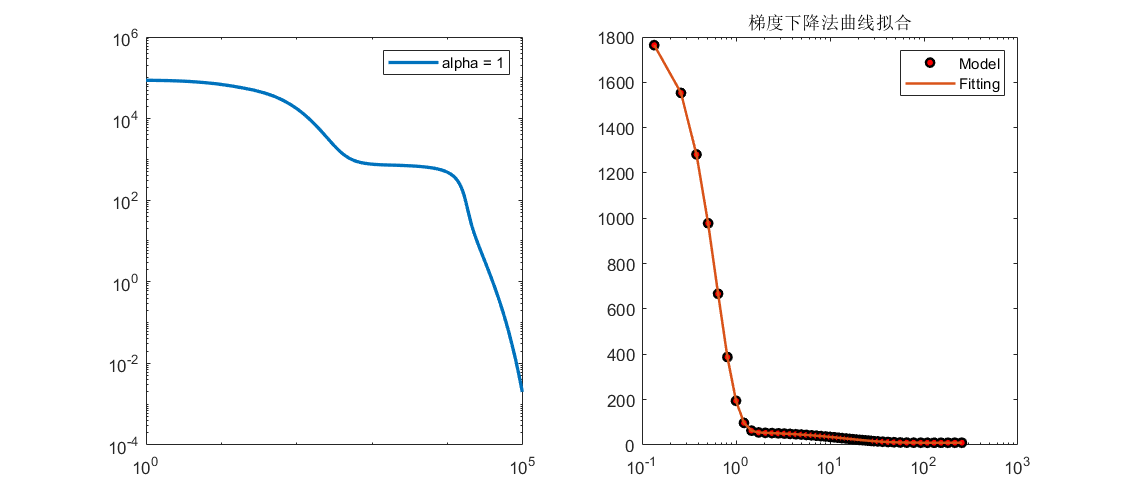

fit = iniA^2 * exp(-t / iniB^2 - 0.5 * iniQMrl^2 * t.^2) + iniAA^2 * exp(-t / iniB^2) + iniC^2;
% 绘图
figure('Position', [50, 50, 900, 400]);
subplot(1, 2, 1)
loglog(J, 'LineWidth', 2)
legend(['alpha = ', num2str(alpha)]);
subplot(1, 2, 2)
semilogx(t, Et, 'ok', 'MarkerFaceColor', 'r', 'MarkerSIze', 5, 'LineWidth', 1.5)
hold on
plot(t, fit, 'LineWidth', 1.5)
hold off
legend('Model', 'Fitting')
title('梯度下降法曲线拟合');